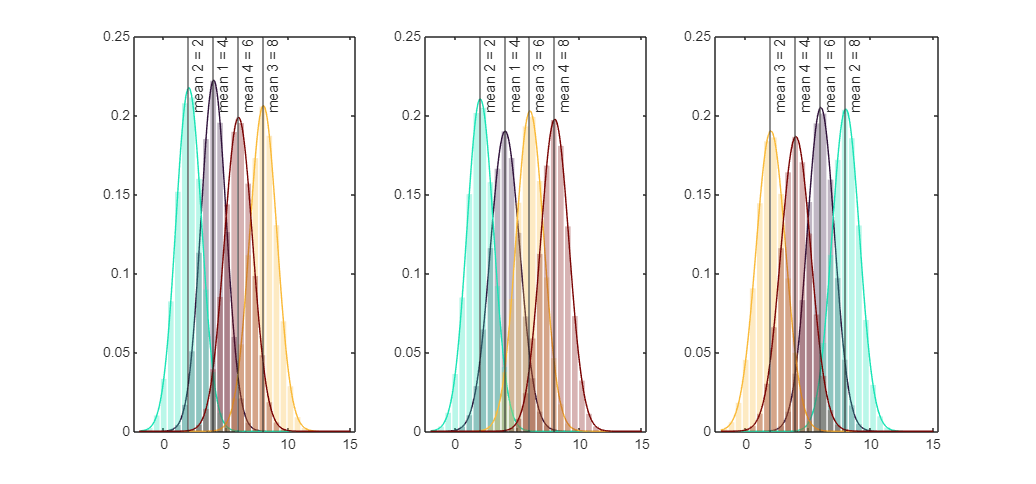

% Jep Brinkmann Thesis HMM example
clc; close all;
k = 4;
d = 30;
n = 3;
m = 1e5;

hmm_options.method = "random";
hmm_options.epsilon = 1/10;
hmm_options.distribution = 'Normal';

cpd_options.maxIter = 2500;
cpd_options.tol = 1e-14;

alpha = 0.85;
rho = 0.90;

cmap = turbo(k);

[T, O, pi, ~, ~] = generateContinuousHMM(k, d, n, hmm_options);

t = -2:0.01:15;
bin_edges = linspace(t(1), t(end), d+1);
bin_centers = (bin_edges(1:end-1) + bin_edges(2:end)) / 2;

O_hists = pdf2pmf(O, bin_centers);


range = t(end) - t(1);

figure('Renderer', 'painters', 'Position', [10 10 1500 700])
for i = 1:n
    subplot(1, n, i);
    O_hist = O_hists{i};

    for j = 1:k
        y = pdf(O{i,j}, t) * range / d;
        plot(t, y, Color=cmap(j,:)); hold on
        xline(O{i,j}.mean, '-',{"mean " + num2str(j) + " = " + num2str(O{i,j}.mean)}); hold on

        bar(bin_centers, O_hist(:, j),'FaceAlpha', 0.3, 'EdgeColor', 'none', FaceColor=cmap(j, :)); hold on
    end
end
hold off;



noiseVariance = 0.0;
[seq, states] = generate_continuous_multivariate_hmm_sequence(T, O, pi, m, noiseVariance);


disc_seq = discretize(seq, d);

[~, mins, maxs] = NormalizeData(seq);

P3 = cell(n, 1);

for i = 1:n
    P3{i} = ProbabilityTensorGenerate(seq(i, :), 3, d);
end





[T_hat, O_hats, ~, ~] = multivariate_coupled_cpd(P3, k, d, n, alpha, rho, cpd_options);
pi_hat = findStationaryDistribution(T_hat')';
[T_hat, O_hats, ~] = remove_hmm_permutation_transition(T, T_hat, O_hats, pi_hat);

t_est = zeros(n, d);
for i = 1:n
    t_est(i, :) = linspace(mins(i), maxs(i), d);
    O_hist = zeros(d, k);
    
    for j = 1:k
        y = pdf(O{i,j}, t_est(i, :)) * range / d;
        O_hist(:, j) = y;
    end
    O_hists{i} = O_hist;
end


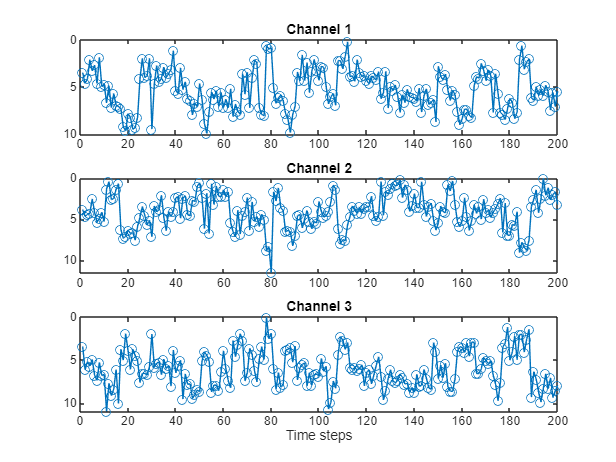


seqPlotLength = 200;

figure();
for i = 1:n
    subplot(n, 1, i);
    plot(seq(i, 1:seqPlotLength)', '-o')
    title(["Channel " + num2str(i)])
    set(gca, 'YDir','reverse');
end
xlabel("Time steps");

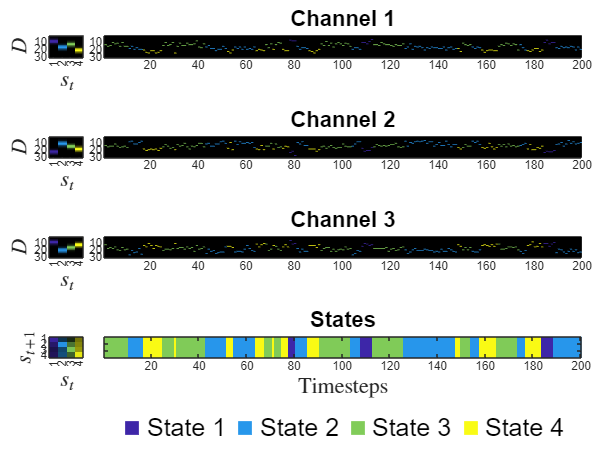



plotMultivariateMatricesAndSequences(disc_seq, states, T, O_hists, seqPlotLength)

figure('Renderer', 'painters', 'Position', [10 10 1500 700]);
tile = tiledlayout(10, n, 'TileSpacing', 'compact', 'Padding', 'compact'); % Replace subplot with tiledlayout

for i = 1:n
    nexttile([9 1]);
    O_hat = O_hats{i};
    O_hist = O_hists{i};
    
    for j = 1:k
        y = pdf(O{i,j}, t) * range / d;

        plot(t, y, 'Color', cmap(j, :)); hold on
        plot(t_est(i, :), O_hist(:, j), 'o', 'Color', cmap(j, :)); hold on
        plot(t_est(i, :), O_hat(:, j), 'x', 'Color', cmap(j, :)); hold on
        bar(t_est(i, :), O_hat(:, j), 'FaceAlpha', 0.3, 'EdgeColor', 'none', 'FaceColor', cmap(j, :)); hold on
    end

    title(['Sequence ' num2str(i)], 'Interpreter','latex', 'FontSize', 14);
    xlabel('x', 'Interpreter','latex', 'FontSize', 14); 
    ylabel('P(x)', 'Interpreter','latex', 'FontSize', 14);

    if i == n
        legend('True PDF', 'True PMF', 'Estimated PMF', 'FontSize', 14);
    end

    hold off;
end

% Add global legend for state colors (dummy axes approach)
% Create invisible axes
ax_dummy = axes('Position', [0 0 1 1], 'Visible', 'off');

% Create dummy lines for legend handles
hold(ax_dummy, 'on');
legend_handles = gobjects(k,1);
for j = 1:k
    legend_handles(j) = plot(ax_dummy, nan, nan, '-', 'Color', cmap(j,:), 'LineWidth', 2);
end

% Create the legend and place it manually below tiledlayout
state_legend = legend(ax_dummy, legend_handles, compose('State %d', 1:k), ...
    'Orientation', 'horizontal', ...
    'Box', 'off', ...
    'FontSize', 14, ...
    'Position', [0.35 0.01 0.3 0.05]);  % Adjust as needed


plotHMMError(T, O_hists, T_hat, O_hats)

Nruns = 10;
noiseRange = exp(linspace(log(0.01),log(10),30));
UncoupledCost = zeros(length(noiseRange), Nruns);
CoupledCost = zeros(length(noiseRange), Nruns);
BWCost = zeros(length(noiseRange), Nruns);

k = 4;
d = 30;
n = 5;
m = 1e5;

hmm_options.method = "random";
hmm_options.distribution = 'Normal';
hmm_options.epsilon = 1/10;

cpd_options.maxIter = 2500;
cpd_options.tol = 1e-14;
cpd_options.th_relerr = 1e-7;
cpd_options.epsilon = 1/10;

alpha = 0.05;
rho = 0.85;



T_hats = cell(n,1);

for j = 1:Nruns
    for i = progress(1:length(noiseRange))

        noiseVariance = noiseRange(i);
        [T, O, pi, ~, ~] = generateContinuousHMM(k, d, n, hmm_options);
        seq = generate_continuous_multivariate_hmm_sequence(T, O, pi, m, noiseVariance);

        [~, mins, maxs] = NormalizeData(seq);
        [T, O_hists] = Discretize_cHMM(T, O, mins, maxs, d);

        % Baum-Welch
       
        [Mu,Cov,A,Pi]=BaumWelch(seq',k);

        T_hat = Stochasticize(A);
        [T_hat, O_hats] = Discretize_cHMM_BW(T_hat, Mu, Cov, mins, maxs, d);
        
        Pbest = MultivariatePermutationFitEmission(O_hists, O_hats);
        T_hat = Pbest * T_hat * Pbest';
        for ii = 1:n
            O_hats{ii} = O_hats{ii} * Pbest';
        end

        BWCost(i, j) = HMMError(T, O_hists, T_hat, O_hats, false);  


        for kk = 1:n
            P3{kk} = ProbabilityTensorGenerate(seq(kk, :), 3, d);
        end

        T_hat = zeros(k,k);
        
        for ii = 1:n
            [A, B, C, ~, ~] = cpd_als_3d(P3{ii}, k, cpd_options);
            O_hat = Stochasticize(B);
            T_hats{ii} = Stochasticize(pinv(Stochasticize(B)) * Stochasticize(C));
        
            Pbest = PermutationFit(T, T_hats{ii}, true);
            T_hats{ii} = Pbest * T_hats{ii} * Pbest';
            T_hat = T_hat + (1/n) * T_hats{ii};
        
            O_hats{ii} = O_hat * Pbest';
        end
    
        UncoupledCost(i, j) = HMMError(T, O_hists, T_hat, O_hats, false);  


        % Coupled CPD
        [T_hat, O_hats, ~, ~] = multivariate_coupled_cpd_2(P3, k, d, n, alpha, rho, cpd_options);
        pi_hat = findStationaryDistribution(T_hat')';
        [T_hat, O_hats, ~] = remove_hmm_permutation_transition(T, T_hat, O_hats, pi_hat);
        
        CoupledCost(i, j) = HMMError(T, O_hists, T_hat, O_hats, false);  
    end
end

Processing:  000%  |                                        | 0/30it [00:00:00<Inf:NaN:NaN, Inf it/s]

Processing:  000%  |                                        | 0/30it [00:00:00<Inf:NaN:NaN, Inf it/s]

Processing:  000%  |                                        | 0/30it [00:00:00<Inf:NaN:NaN, Inf it/s]

Processing:  000%  |                                        | 0/30it [00:00:00<Inf:NaN:NaN, Inf it/s]

Processing:  000%  |                                        | 0/30it [00:00:00<Inf:NaN:NaN, Inf it/s]

Processing:  000%  |                                        | 0/30it [00:00:00<Inf:NaN:NaN, Inf it/s]

Processing:  000%  |                                        | 0/30it [00:00:00<Inf:NaN:NaN, Inf it/s]

Processing:  000%  |                                        | 0/30it [00:00:00<Inf:NaN:NaN, Inf it/s]

Processing:  000%  |                                        | 0/30it [00:00:00<Inf:NaN:NaN, Inf it/s]

Processing:  000%  |                                        | 0/30it [00:00:00<Inf:NaN:NaN, Inf it/s]


save("PerformanceTests/ContinuousNoiseCost2", "BWCost", "CoupledCost", "UncoupledCost", "noiseRange")

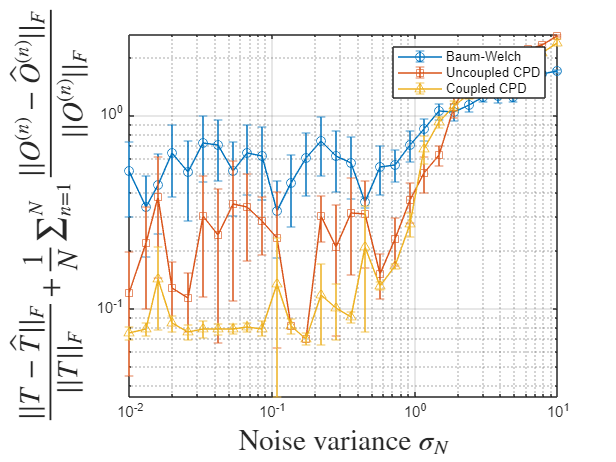

load("PerformanceTests/ContinuousNoiseCost2")

noiseRange = round(noiseRange, 3);

cmap = orderedcolors("gem");

[BWCostSTD, BWCostMean] = std(BWCost, 0, 2);
[UncoupledCostSTD, UncoupledCostMean] = std(UncoupledCost, 0, 2);
[CoupledCostSTD, CoupledCostMean] = std(CoupledCost, 0, 2);


figure()
errorbar(noiseRange, BWCostMean, BWCostSTD/2, '-o'); hold on;
errorbar(noiseRange, UncoupledCostMean, UncoupledCostSTD/2, '-s'); hold on;
errorbar(noiseRange, CoupledCostMean, CoupledCostSTD/2, '-^'); hold on;

% diff = max(UncoupledCost, [], "all") - min(UncoupledCost, [], "all");
% ylim([min(UncoupledCost, [], "all") - diff * 0.01, max(UncoupledCost, [], "all") + diff * 0.01])
set(gca,'YScale','log', 'XScale', 'log');
grid on; legend("Baum-Welch", "Uncoupled CPD", "Coupled CPD", Location="northeast");
% title("HMM error over noise variance",'FontSize',24,'FontWeight','bold');
ylabel("$\frac{||T - \hat{T}||_F}{||T||_F} + \frac{1}{N} \sum_{n=1}^N \frac{||O^{(n)} - \hat{O}^{(n)}||_F}{||O^{(n)}||_F}$", "Interpreter","latex",'FontSize',20,'FontWeight','bold')
xlabel("Noise variance $\sigma_N$","Interpreter","latex",'FontSize',20,'FontWeight','bold');

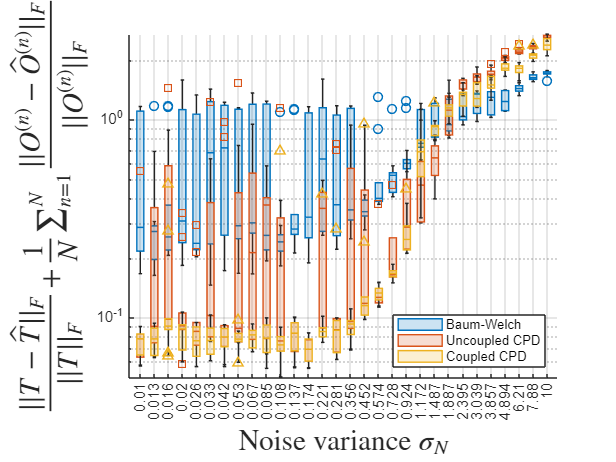


figure()
cmap = orderedcolors("gem");

boxchart(BWCost', "MarkerStyle", 'o'); hold on;
boxchart(UncoupledCost', "MarkerStyle", 's'); hold on;
boxchart(CoupledCost', "MarkerStyle", '^'); hold on;
xticklabels(noiseRange);
set(gca,'YScale','log');
grid on;
ylabel("$\frac{||T - \hat{T}||_F}{||T||_F} + \frac{1}{N} \sum_{n=1}^N \frac{||O^{(n)} - \hat{O}^{(n)}||_F}{||O^{(n)}||_F}$", "Interpreter","latex",'FontSize',20,'FontWeight','bold')
xlabel("Noise variance $\sigma_N$","Interpreter","latex",'FontSize',20,'FontWeight','bold');
hold off; legend("Baum-Welch", "Uncoupled CPD", "Coupled CPD", Location="southeast");

ans = 0.1571

ans = 0.0604

ans = 0.0042

ans = 0.0628

ans = 0.0604

ans = 0.1538

ans = 5.6607e-05

ans = 0.0051

ans = 0.0042

ans = 5.6607e-05

ans = 0.1457

ans = 0.0642

ans = 0.0628

ans = 0.0051

ans = 0.0642

ans = 0.1405